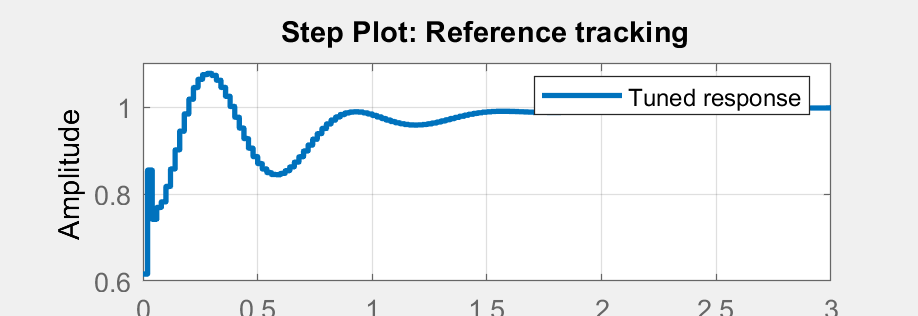

% source: http://ctms.engin.umich.edu/CTMS/index.php?example=Suspension&section=ControlStateSpace
% source: https://pdfs.semanticscholar.org/249a/26b6cf5336f5b42a1797d44aadb49360d41d.pdf

%{
(M1)    1/4 bus body mass                        2500 kg
(M2)    suspension mass                          320 kg
(K1)    spring constant of suspension system     80,000 N/m
(K2)    spring constant of wheel and tire        500,000 N/m
(b1)    damping constant of suspension system    350 N.s/m
(b2)    damping constant of wheel and tire       15,020 N.s/m
(U)     control force
%}
clc;
clear all;
close all;

global A;
global B;
global control;

m1 = 2500;
m2 = 320;
k1 = 80000;
k2 = 500000;
b1 = 350;
b2 = 15020;

A=[0                 1   0                                              0
  -(b1*b2)/(m1*m2)   0   ((b1/m1)*((b1/m1)+(b1/m2)+(b2/m2)))-(k1/m1)   -(b1/m1)
   b2/m2             0  -((b1/m1)+(b1/m2)+(b2/m2))                      1
   k2/m2             0  -((k1/m1)+(k1/m2)+(k2/m2))                      0];
Bu = [0; 1/m1; 0; (1/m1)+(1/m2)];
Du = 0;
B=[0                 0
   1/m1              (b1*b2)/(m1*m2)
   0                -(b2/m2)
   (1/m1)+(1/m2)    -(k2/m2)];
C=[0 0 1 0];
D=[0 0];

sys=ss(A,B,C,D);

x0 = [0; 0];
% sysd = c2d(sys, 0.02);
% pidTuner(sysd,'pid')

# Timing Parameters

dt = 0.02;
t_total = 10;
t_span = 0:dt:t_total;

% target measurement - pulse
ref_fuc = @(i) 5-mod(floor(i*dt/4),2);
ref = zeros(size(t_span,2),1);
for i = 1:length(ref)
    ref(i,1) = ref_fuc(i);
end

# PID Parameters

global windupGuard;
global proportional_gain;
global integral_gain;
global derivative_gain;
global prev_error;
global int_error;
global control;

% set these as needed
control = 0;
windupGuard = 100;
proportional_gain = 9.6e5;
integral_gain = 1.206e6;;
derivative_gain = 5.678e4;
 
% this is the zeroize function
prev_error = 0.0;
int_error = 0.0;

% call update function
%pid_update(19, 1.0)

# Simulation - No attacks

close all

% this is the zeroize function
prev_error = 0.0;
int_error = 0.0;

x = zeros(size(t_span,2),size(x0,1));
x(1,:) = x0';
xlast = x0;
y = C * x0;

for i = 2:(t_total/dt+1)
    error = ref(i,1) - y(end,1);
    pid_update(error, dt);
    controlaug = [control u()] 
%     [y,t,xtemp] = lsim(sys,control(end,1)*ones(size(0:dt:dt))',(0:dt:dt),xlast);
    [T, xtemp] = ode45(@dynamics, [0 dt], xlast);
    y = C * xtemp(end,:)';
    xlast = xtemp(end,:);
    x(i,:) = xlast;
    xlast = xlast';
end

plot(t_span,ref(:,1),'b--',t_span,x(:,1),'k', 'LineWidth', 1);
set(gca,'FontSize',12)
ylabel('Motor Angular Velocity - rad/s','FontSize',15);
xlabel('Time - second','FontSize',15);
legend('reference','normal','Location','SouthEast','FontSize',15);

function dxdt = dynamics(t, x)

global A;
global B;
global control;

dxdt = A*x + B*control;

end